clear;
mklist = 'o+*sd<p';
alglist = {'MatchSync', 'MatchLift', 'MatchALS', 'JOMGM', 'CDMGM', 'FMGM'};
cmap = lines(7);
cmap = cmap(2:end, :);
cmap(end, :) = 0;

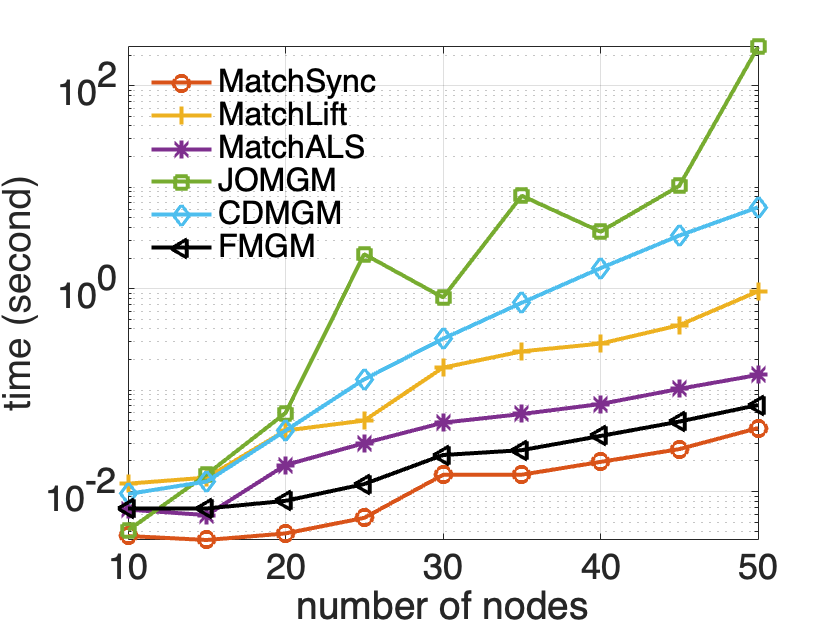

tcost = importdata('tcost1.mat');
node_num = 50:-5:10;
figure, hold on; 
for k = 1:length(alglist)
    plot(node_num, tcost(:, k), ['-', mklist(k)], 'DisplayName', alglist{k}, 'Color', cmap(k, :));
end
hold off;
set(gca, 'YScale', 'log')
legend('Location', 'northwest');
xlabel('number of nodes');
ylabel('time (second)');
% ylim([0, 10]);
exportgraphics(gcf, ['./imgs/', 'tcost1.pdf']);

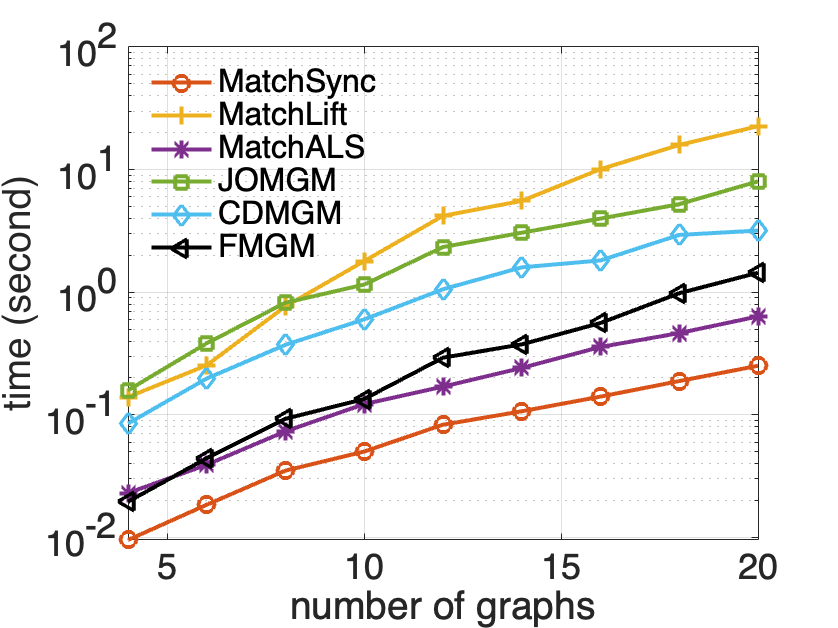

tcost = importdata('tcost2.mat');
graph_num = 20:-2:4;
figure, hold on; 
for k = 1:length(alglist)
    plot(graph_num, tcost(:, k), ['-', mklist(k)], 'DisplayName', alglist{k}, 'Color', cmap(k, :));
end
hold off;
set(gca, 'YScale', 'log')
legend('Location', 'northwest');
xlabel('number of graphs');
ylabel('time (second)');
% ylim([0, 20]);
xlim([4, 20]);
exportgraphics(gcf, ['./imgs/', 'tcost2.pdf']);